## 题目1

%1
% 求和计算
S = sum(1 ./ (2 * (1:10) - 1));
disp(['S = ', num2str(S)]);

S = 2.1333



%2
% 定义无穷级数的和函数
syms n x;
S = symsum(n^2 / 5^n, n, 1, Inf);
disp('级数的和:');

级数的和:


disp(S);

$$\frac{15}{32}$$

## 题目2

% 泰勒展开
syms x;
T = taylor(log(x), x, 'ExpansionPoint', 1, 'Order', 6);
disp('ln(x)的泰勒级数展开:');

ln(x)的泰勒级数展开:


disp(T);

$$x-\frac{{\left(x-1\right)}^{2}}{2}+\frac{{\left(x-1\right)}^{3}}{3}-\frac{{\left(x-1\right)}^{4}}{4}+\frac{{\left(x-1\right)}^{5}}{5}-1$$

## 题目3

% 1
syms x;
eq1 = log(1 + x) == 5 / (1 + sin(x));
sol1 = solve(eq1, x);

disp('ln(1 + x) = 5 / (1 + sin(x)) 的解:');

ln(1 + x) = 5 / (1 + sin(x)) 的解:


disp(sol1);

$$59.469598249169511960332129463357$$


% 2
syms x;
eq2 = x^2 + 9 * sqrt(x + 1) - 1 == 0;
sol2 = solve(eq2, x);
disp('x^2 + 9*sqrt(x+1) - 1 = 0 的解:');

x^2 + 9*sqrt(x+1) - 1 = 0 的解:


disp(sol2);

$$-1$$


% 3
syms x;
eq3 = 3*x*exp(x) + 5*sin(x) - 78.5 == 0;
sol3 = vpasolve(eq3, x); % 使用数值解
disp('3x*e^x + 5*sin(x) - 78.5 = 0 的解:');

3x*e^x + 5*sin(x) - 78.5 = 0 的解:


disp(sol3);

$$2.3599419584772910151699327715486$$


% 4
syms x y;
eq4_1 = sqrt(x^2 + y^2) - 100 == 0;
eq4_2 = 3*x + 5*y - 8 == 0;
[sol_x, sol_y] = solve([eq4_1, eq4_2], [x, y]);
disp('方程组的解:');

方程组的解:


disp(['x = ', char(sol_x)]);

x = [(10*21246^(1/2))/17 + 12/17; 12/17 - (10*21246^(1/2))/17]


disp(['y = ', char(sol_y)]);

y = [20/17 - (6*21246^(1/2))/17; (6*21246^(1/2))/17 + 20/17]


## 题目4

% 符号解
syms y(x);
Dy = diff(y, x);
eq = diff(y, x, 2) + 4*diff(y, x) + 29*y == 0;
conds = [y(0) == 0, subs(Dy, x, 0) == 15];
sol = dsolve(eq, conds);
disp('符号解:');

符号解:


disp(sol);

$$3\,\sin\left(5\,x\right)\,{\mathrm{e}}^{-2\,x}$$

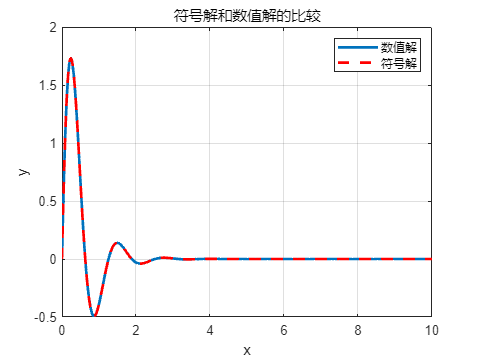


% 数值解
f = @(t, Y) [Y(2); -4*Y(2) - 29*Y(1)];
[t, Y] = ode45(f, [0, 10], [0, 15]); % 数值求解
figure;
plot(t, Y(:, 1), 'LineWidth', 2);
hold on;
fplot(matlabFunction(sol), [0, 10], '--r', 'LineWidth', 2);
legend('数值解', '符号解');
title('符号解和数值解的比较');
xlabel('x');
ylabel('y');
grid on;

## 题目5

% 符号解
syms x(t) y(t) z(t);
eq1 = diff(x, t) == 2*x - 3*y + 3*z;
eq2 = diff(y, t) == 4*x - 5*y + 3*z;
eq3 = diff(z, t) == 4*x - 4*y + 2*z;
sol = dsolve([eq1, eq2, eq3]);
disp('一般解:');

一般解:


disp(['x(t) = ', char(sol.x)]);

x(t) = C1*exp(-t) + C3*exp(2*t)


disp(['y(t) = ', char(sol.y)]);

y(t) = C1*exp(-t) + C2*exp(-2*t) + C3*exp(2*t)


disp(['z(t) = ', char(sol.z)]);

z(t) = C2*exp(-2*t) + C3*exp(2*t)
